Лабораторная работа №2

Управление для плоского робота открытой кинематики

Топольницкий А.

Вариант №53

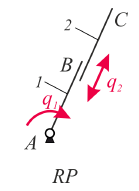

Рисунок 1.

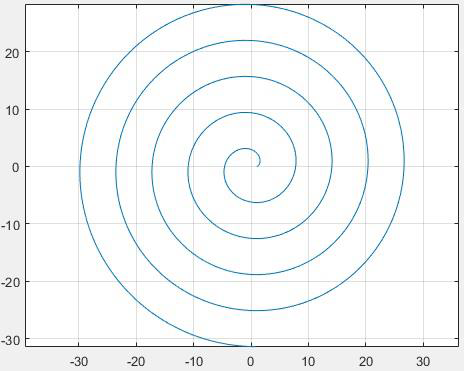

Рисунок 2.

Исходные данные:

- Задана конфигурация робота, изображённая на Рисунке 1. Первое звено вращательное, второе призматическое, то есть схема RP

- Необходимо реализовать траекторию, изображённую на рисунке 2.

- Параметры звеньев следующие: $L1 = 0.56  \; m, \; M1 = 0.72 \; kg, \; L2 =0.59  \; m , \; M2 = 0.57  \; kg$

Задание:

- Реализовать управление плоским роботом по положению с помощью ПИД регулятора (без построения модели робота);

- Реализовать управление плоским роботом по положению на основе динамической модели;

- Реализовать управление плоским роботом по импедансу с компенсацией гравитации

- Сравнить поведение и производительность робота при разных способах управления

Ход работы:

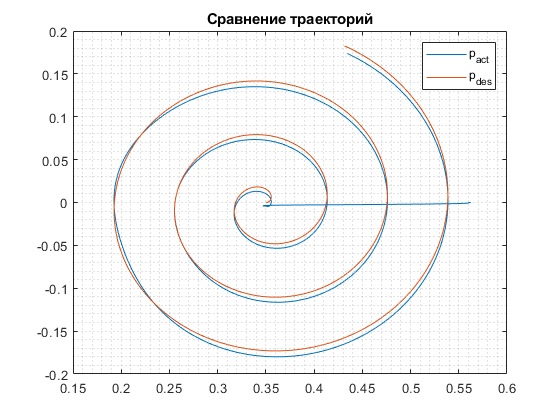

L1 = 0.56; %Length 1 link m
L2 = 0.59; %Length 2 link m
AB = [L1 0.1 0.1]; %scales 1st link
BC = [L2 0.05 0.05]; %scales 2d link
m1 = 0.72; %Mass 1 kg
m2 = 0.57; %Mass 2 kg
Base = [0.2*L1 0.2*L1 0.2*L1]; %Base parametrs


figure;
plot(out.position.p_act.Data(:,1), out.position.p_act.Data(:,2))
grid minor
hold on
plot(out.position.p_des.Data(:,1), out.position.p_des.Data(:,2))
title('Сравнение траекторий')
legend('p_{act}','p_{des}')

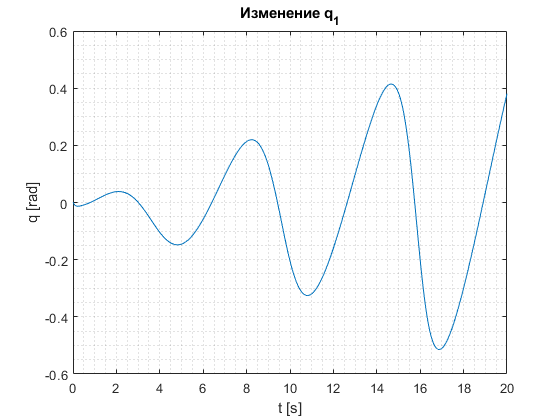

figure;
plot(out.position.q1_act.time, out.position.q1_act.Data)
grid minor
title('Изменение q_1')
xlabel('t [s]');
ylabel('q [rad]');

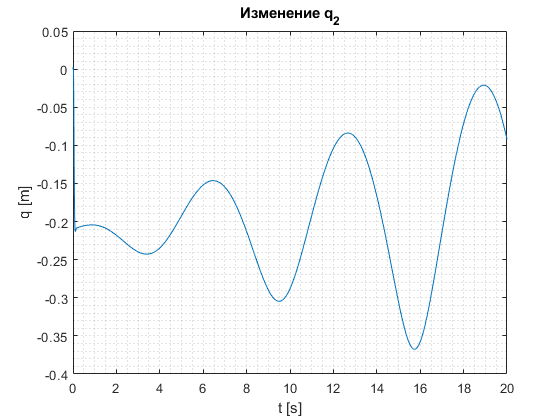


figure;
plot(out.position.q2_act.time, out.position.q2_act.Data)
grid minor
title('Изменение q_2')
xlabel('t [s]');
ylabel('q [m]');

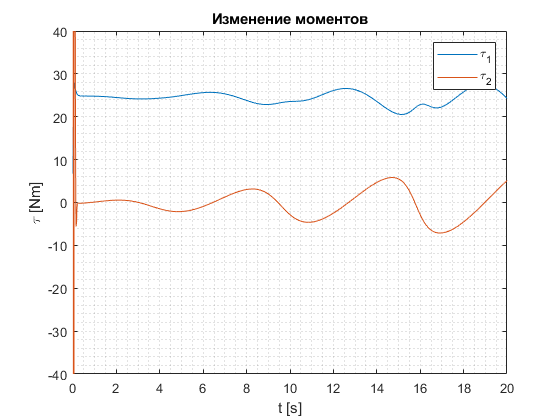

figure;
plot(out.tau.time,out.tau.Data(:,1))
hold on
plot(out.tau.time, out.tau.Data(:,2))
grid minor;
title('Изменение моментов')
legend('\tau_1', '\tau_2');
xlabel('t [s]');
ylabel('\tau [Nm]');
ylim([-40 40]);